# Exploratory Data Analysis (TS03 - Month 1 Visit)

## Initialization - Data Setup

Import the processed data obtained from Tourette Graphical User Interface programs (SyncData and renderData). The processed data will contain time matched data for easy visualization. 

clear;clc;close all;
cd('G:\TS03\2016_11_07');
TrialID = dir('Processed*.mat');
for trial = 1:length(TrialID)
    ProcessedData(trial) = load(TrialID(trial).name);
    TaskID{trial} = TrialID(trial).name(31:end-4);
end

## Tic Prevalence Analysis

This section will look into how often does tic occur during the full recording period. Only periods containing DBS recording are considered in this case. 

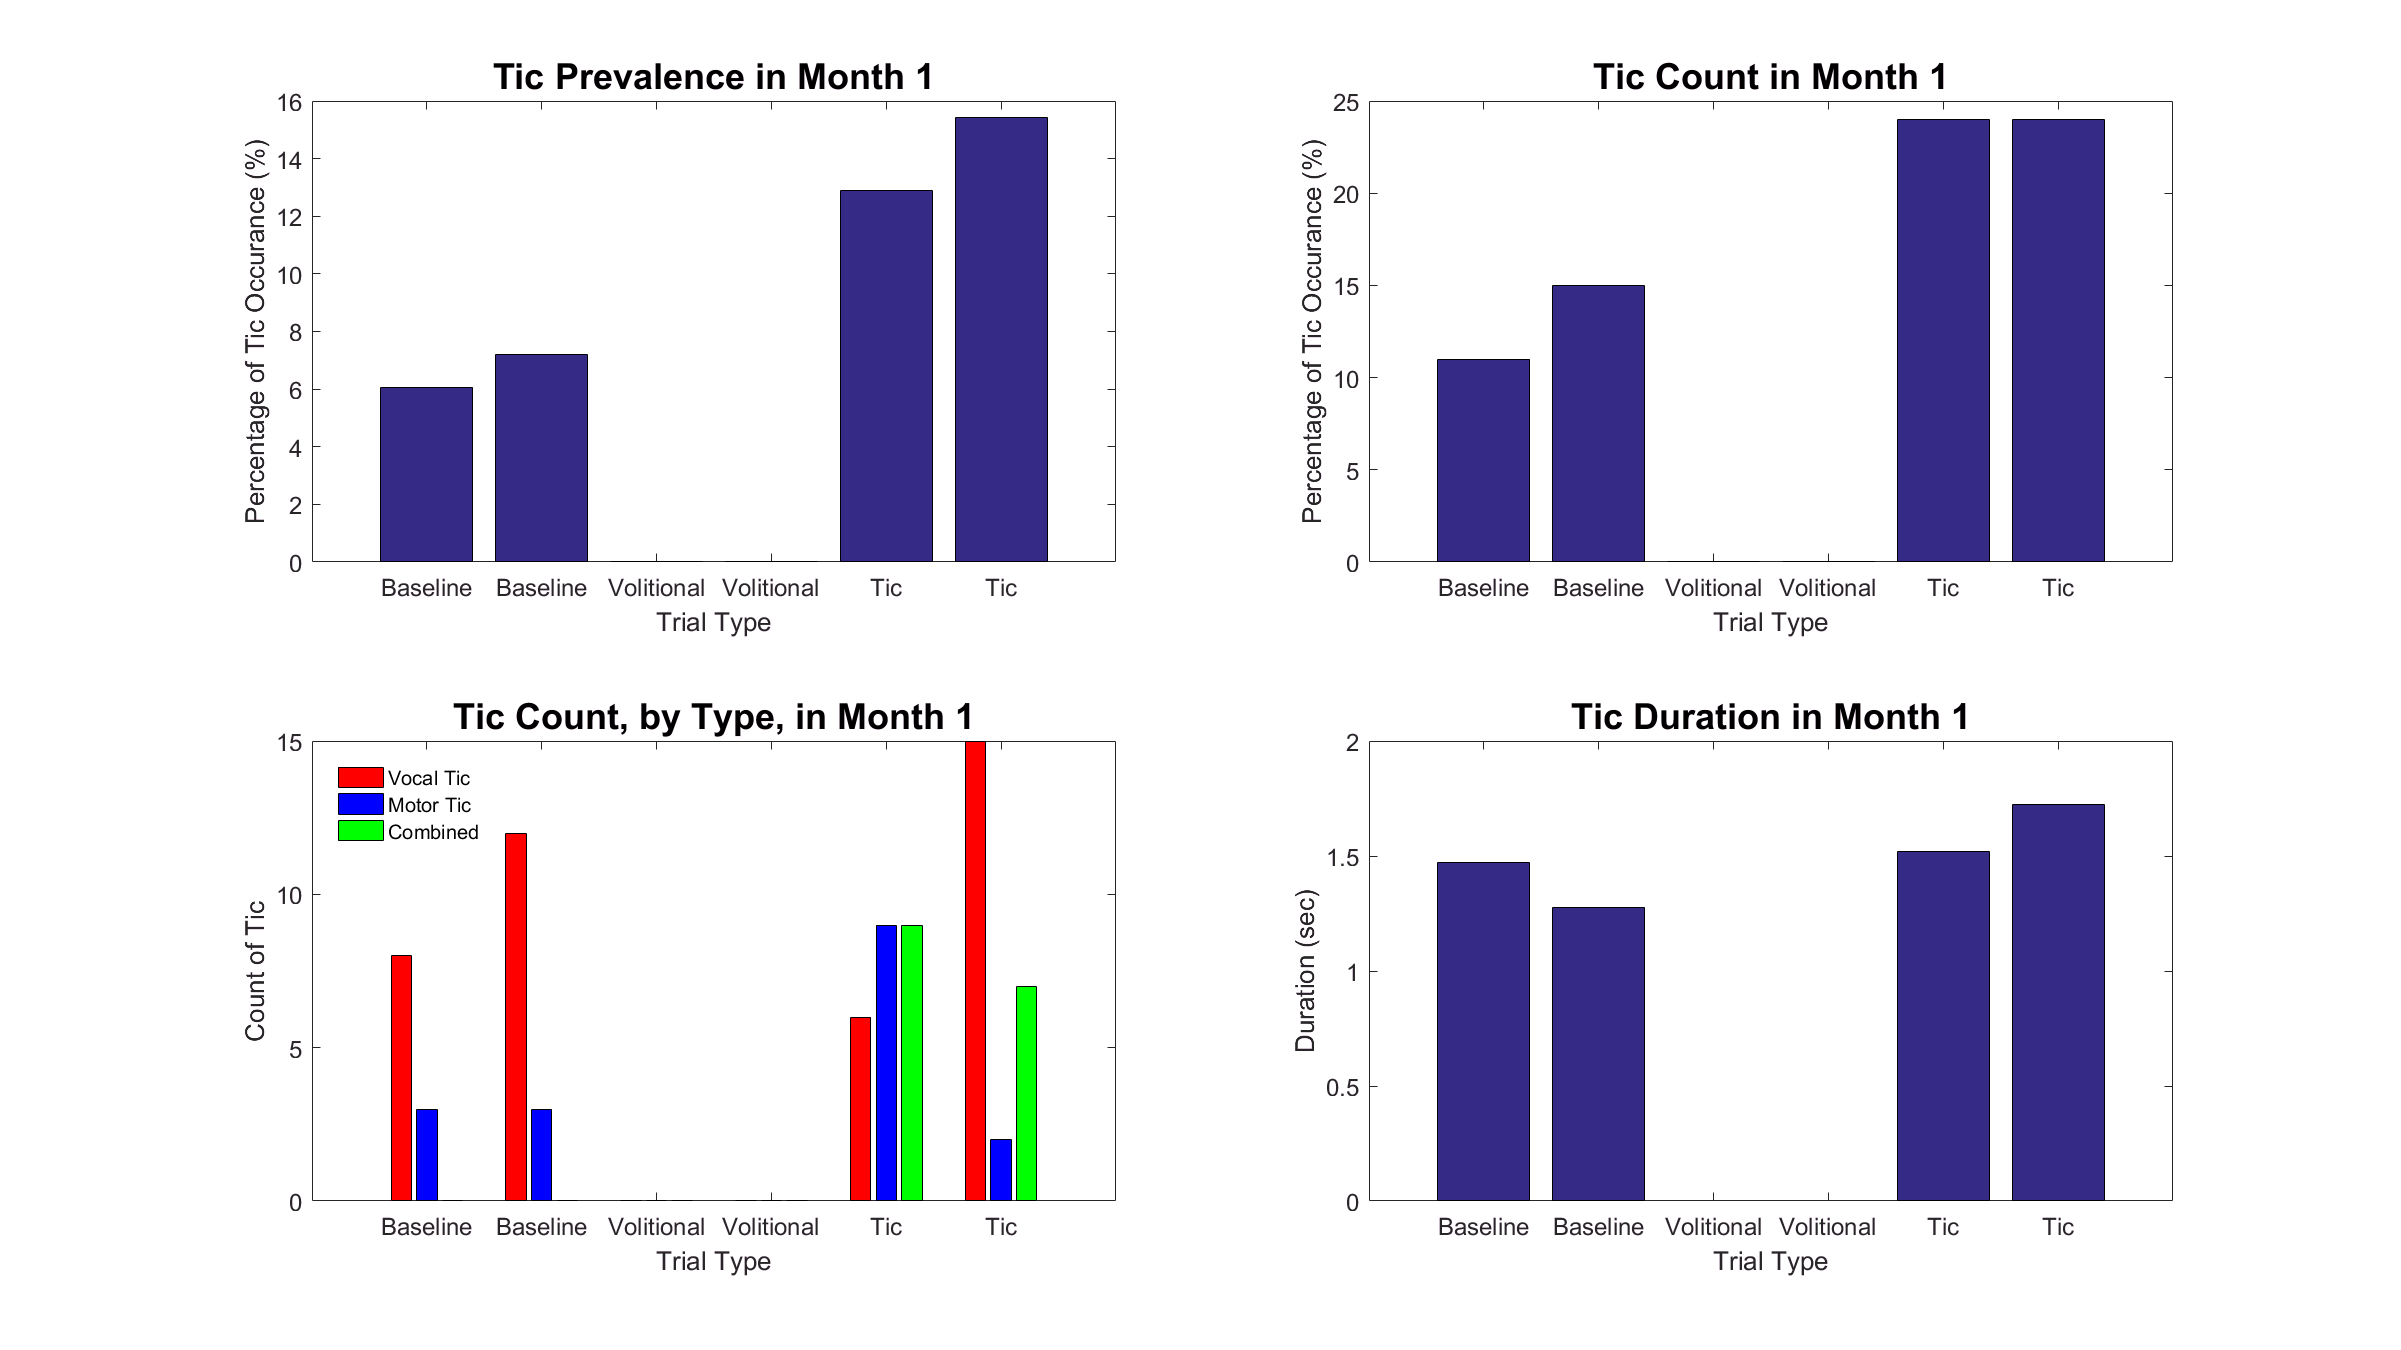

% Compute the Tic Parameters 
TicPercentage = zeros(1,length(ProcessedData));
TicType = zeros(length(ProcessedData),3);
AverageTicDuration = zeros(length(ProcessedData),1);
for trial = 1:length(ProcessedData)
    DBS_RecordingTime = [-max(ProcessedData(trial).DBS_Bias) -min(ProcessedData(trial).DBS_Bias)+max(ProcessedData(trial).Left_DBS.TimeRange)];
    PeriodSelection = ProcessedData(trial).Marker.time - ProcessedData(trial).EMG_Bias > DBS_RecordingTime(1) & ...
        ProcessedData(trial).Marker.time - ProcessedData(trial).EMG_Bias < DBS_RecordingTime(2);
    TicPercentage(trial) = sum(ProcessedData(trial).Marker.data(PeriodSelection) ~= 0) / sum(PeriodSelection);
    
    TicRecording(trial).Count = 0;
    EndIndex = 0;
    while true
        Index = find(ProcessedData(trial).Marker.data(EndIndex+1:end) ~= 0, 1) + EndIndex;
        EndIndex = find(ProcessedData(trial).Marker.data(Index+1:end) == 0, 1) + Index;
        if isempty(Index)
            break;
        end
        TicRecording(trial).Count = TicRecording(trial).Count + 1;
        TicRecording(trial).Type(TicRecording(trial).Count) = ProcessedData(trial).Marker.data(Index);
        TicRecording(trial).Duration(TicRecording(trial).Count) = ProcessedData(trial).Marker.time(EndIndex) - ProcessedData(trial).Marker.time(Index);
        TicRecording(trial).Onset(TicRecording(trial).Count) = ProcessedData(trial).Marker.time(Index) - ProcessedData(trial).EMG_Bias;
    end
    
    TicType(trial,1) = sum(TicRecording(trial).Type == 1);
    TicType(trial,2) = sum(TicRecording(trial).Type == 2);
    TicType(trial,3) = sum(TicRecording(trial).Type == 3);
    AverageTicDuration(trial) = mean(TicRecording(trial).Duration);
end

% Visualization
largeFigure(0, [1600 900]); clf; hold on;
subplot(2,2,1); cla;
bar(1:length(ProcessedData), TicPercentage * 100);
xlabel('Trial Type','fontsize',13);
ylabel('Percentage of Tic Occurance (%)','fontsize',13);
set(gca,'XTick',1:length(ProcessedData),'XTickLabel',TaskID);
set(gca,'FontSize',12);
title('Tic Prevalence in Month 1','fontsize',18);

subplot(2,2,2); cla;
bar(1:length(ProcessedData), [TicRecording.Count]);
xlabel('Trial Type','fontsize',13);
ylabel('Tic Count','fontsize',13);
set(gca,'XTick',1:length(ProcessedData),'XTickLabel',TaskID);
set(gca,'FontSize',12);
title('Tic Count in Month 1','fontsize',18);

subplot(2,2,3); cla;
hb = bar(1:length(ProcessedData), TicType, 'grouped');
set(hb(1), 'FaceColor','r')
set(hb(2), 'FaceColor','b')
set(hb(3), 'FaceColor','g')
xlabel('Trial Type','fontsize',13);
ylabel('Count of Tic','fontsize',13);
set(gca,'XTick',1:length(ProcessedData),'XTickLabel',TaskID);
set(gca,'FontSize',12);
legendFont(gca,{'Vocal Tic','Motor Tic','Combined'},{'fontsize',10,'location','northwest'});
title('Tic Count, by Type, in Month 1','fontsize',18);

subplot(2,2,4); cla;
bar(1:length(ProcessedData), AverageTicDuration);
xlabel('Trial Type','fontsize',13);
ylabel('Duration (sec)','fontsize',13);
set(gca,'XTick',1:length(ProcessedData),'XTickLabel',TaskID);
set(gca,'FontSize',12);
title('Tic Duration in Month 1','fontsize',18);

***Results:***

The "Volitional" trials are not labeled yet. The patient seems to have less tic during "Baseline" trial, which is when we instructed her to control her tic as much as possible. On the other hand, during "Tic" trial, she develop more Tic. This is as expected. From the graphical representation, it seems she is capable of controlling half of her tic by active suppression. Whether 14% of the time having Tic is a high number or not depends on the Clinician feedback. 

The tic is highly prevalence in vocal tic. This is often seen as sniffing of nose accompany with tremoring. There are not any combined Tic during baseline, the patient is capable of suppressing most of her motor symptoms but not so much for the vocal symptoms. The duration, on the other hand, remain mostly the same whether suppressing or not.

## Tic Onset Computation

In this section, we will try to sector out snippets of Tic recording in the recording. Since we found out that the average Tic duration is around 1 second, we are going to sector out data from 5 seconds before Tic to 3 seconds after Tic. This onset analysis consider all three type of tic identified in previous section as the same tic to simplify the analysis.

The criteria during this analysis is to store both Left Device and Right Device together for combined visualization. However, since there are time-shift for the Left and Right recording, In addition, a variable named **TicRecording.DataCompletion **will indicate whether the signal is completed or not. 

- 0 - No Data Available

- 1 - Only the first part contain data, the rest are 0s

- 2 - Only the last part contain data, the initials are 0s

- 3 - Contain All Data

% Compute the Tic Onset Structure

TimeLimit = [-3 3];

for trial = 1:length(ProcessedData)
    IndexRange = ProcessedData(trial).Right_DBS.SamplingRate*TimeLimit(1):ProcessedData(trial).Right_DBS.SamplingRate*TimeLimit(2);
    TicRecording(trial).ThaData = zeros(length(IndexRange),TicRecording(trial).Count,2);
    TicRecording(trial).CorData = zeros(length(IndexRange),TicRecording(trial).Count,2);
    TicRecording(trial).DataCompletion = zeros(TicRecording(trial).Count,2);
    for TicID = 1:TicRecording(trial).Count
        [TD,OnsetIndex] = min(abs(ProcessedData(trial).Left_DBS.TimeRange - ProcessedData(trial).DBS_Bias(1) - TicRecording(trial).Onset(TicID)));
        if TD > 0.1
            OnsetIndex = [];
        end
        if ~isempty(OnsetIndex)
            if OnsetIndex + IndexRange(end) >= length(ProcessedData(trial).Left_DBS.data)
                TicRecording(trial).ThaData(1:end-(OnsetIndex+IndexRange(end)-length(ProcessedData(trial).Left_DBS.data)),TicID,1) = ProcessedData(trial).Left_DBS.data(OnsetIndex + IndexRange(1) : end , 1);
                TicRecording(trial).CorData(1:end-(OnsetIndex+IndexRange(end)-length(ProcessedData(trial).Left_DBS.data)),TicID,1) = ProcessedData(trial).Left_DBS.data(OnsetIndex + IndexRange(1) : end , 3);
                TicRecording(trial).DataCompletion(TicID,1) = 1;
            elseif OnsetIndex + IndexRange(1) <= 1
                TicRecording(trial).ThaData(end-OnsetIndex-IndexRange(end)+1:end,TicID,1) = ProcessedData(trial).Left_DBS.data(1 : OnsetIndex + IndexRange(end) , 1);
                TicRecording(trial).CorData(end-OnsetIndex-IndexRange(end)+1:end,TicID,1) = ProcessedData(trial).Left_DBS.data(1 : OnsetIndex + IndexRange(end) , 3);
                TicRecording(trial).DataCompletion(TicID,1) = 2;
            else
                TicRecording(trial).ThaData(:,TicID,1) = ProcessedData(trial).Left_DBS.data(OnsetIndex + IndexRange , 1);
                TicRecording(trial).CorData(:,TicID,1) = ProcessedData(trial).Left_DBS.data(OnsetIndex + IndexRange , 3);
                TicRecording(trial).DataCompletion(TicID,1) = 3;
            end
        end
        
        [TD,OnsetIndex] = min(abs(ProcessedData(trial).Right_DBS.TimeRange - ProcessedData(trial).DBS_Bias(2) - TicRecording(trial).Onset(TicID)));
        if TD > 0.1
            OnsetIndex = [];
        end
        if ~isempty(OnsetIndex)
            if OnsetIndex + IndexRange(end) >= length(ProcessedData(trial).Right_DBS.data)
                TicRecording(trial).ThaData(1:end-(OnsetIndex+IndexRange(end)-length(ProcessedData(trial).Left_DBS.data)),TicID,2) = ProcessedData(trial).Right_DBS.data(OnsetIndex + IndexRange(1) : end , 1);
                TicRecording(trial).CorData(1:end-(OnsetIndex+IndexRange(end)-length(ProcessedData(trial).Left_DBS.data)),TicID,2) = ProcessedData(trial).Right_DBS.data(OnsetIndex + IndexRange(1) : end , 3);
                TicRecording(trial).DataCompletion(TicID,2) = 1;
            elseif OnsetIndex + IndexRange(1) <= 1
                TicRecording(trial).ThaData(end-OnsetIndex-IndexRange(end)+1:end,TicID,2) = ProcessedData(trial).Right_DBS.data(1 : OnsetIndex + IndexRange(end) , 1);
                TicRecording(trial).CorData(end-OnsetIndex-IndexRange(end)+1:end,TicID,2) = ProcessedData(trial).Right_DBS.data(1 : OnsetIndex + IndexRange(end) , 3);
                TicRecording(trial).DataCompletion(TicID,2) = 2;
            else
                TicRecording(trial).ThaData(:,TicID,2) = ProcessedData(trial).Right_DBS.data(OnsetIndex + IndexRange , 1);
                TicRecording(trial).CorData(:,TicID,2) = ProcessedData(trial).Right_DBS.data(OnsetIndex + IndexRange , 3);
                TicRecording(trial).DataCompletion(TicID,2) = 3; 
            end
        end
    end
end

## Pre-Tic / Post-Tic Power Spectral Analysis (Cortical Data) `[To Be Complete: Add Baseline In Comparison]`

After collecting all datas, we will compute Power Spectral Density using Maximum Entropy Method (BCI2000 Source Code). The Comparison is first made to compare Pre-Tic and Post-Tic. In this analysis section, I only look at Cortical Data and that if the data has full 8 seconds recording

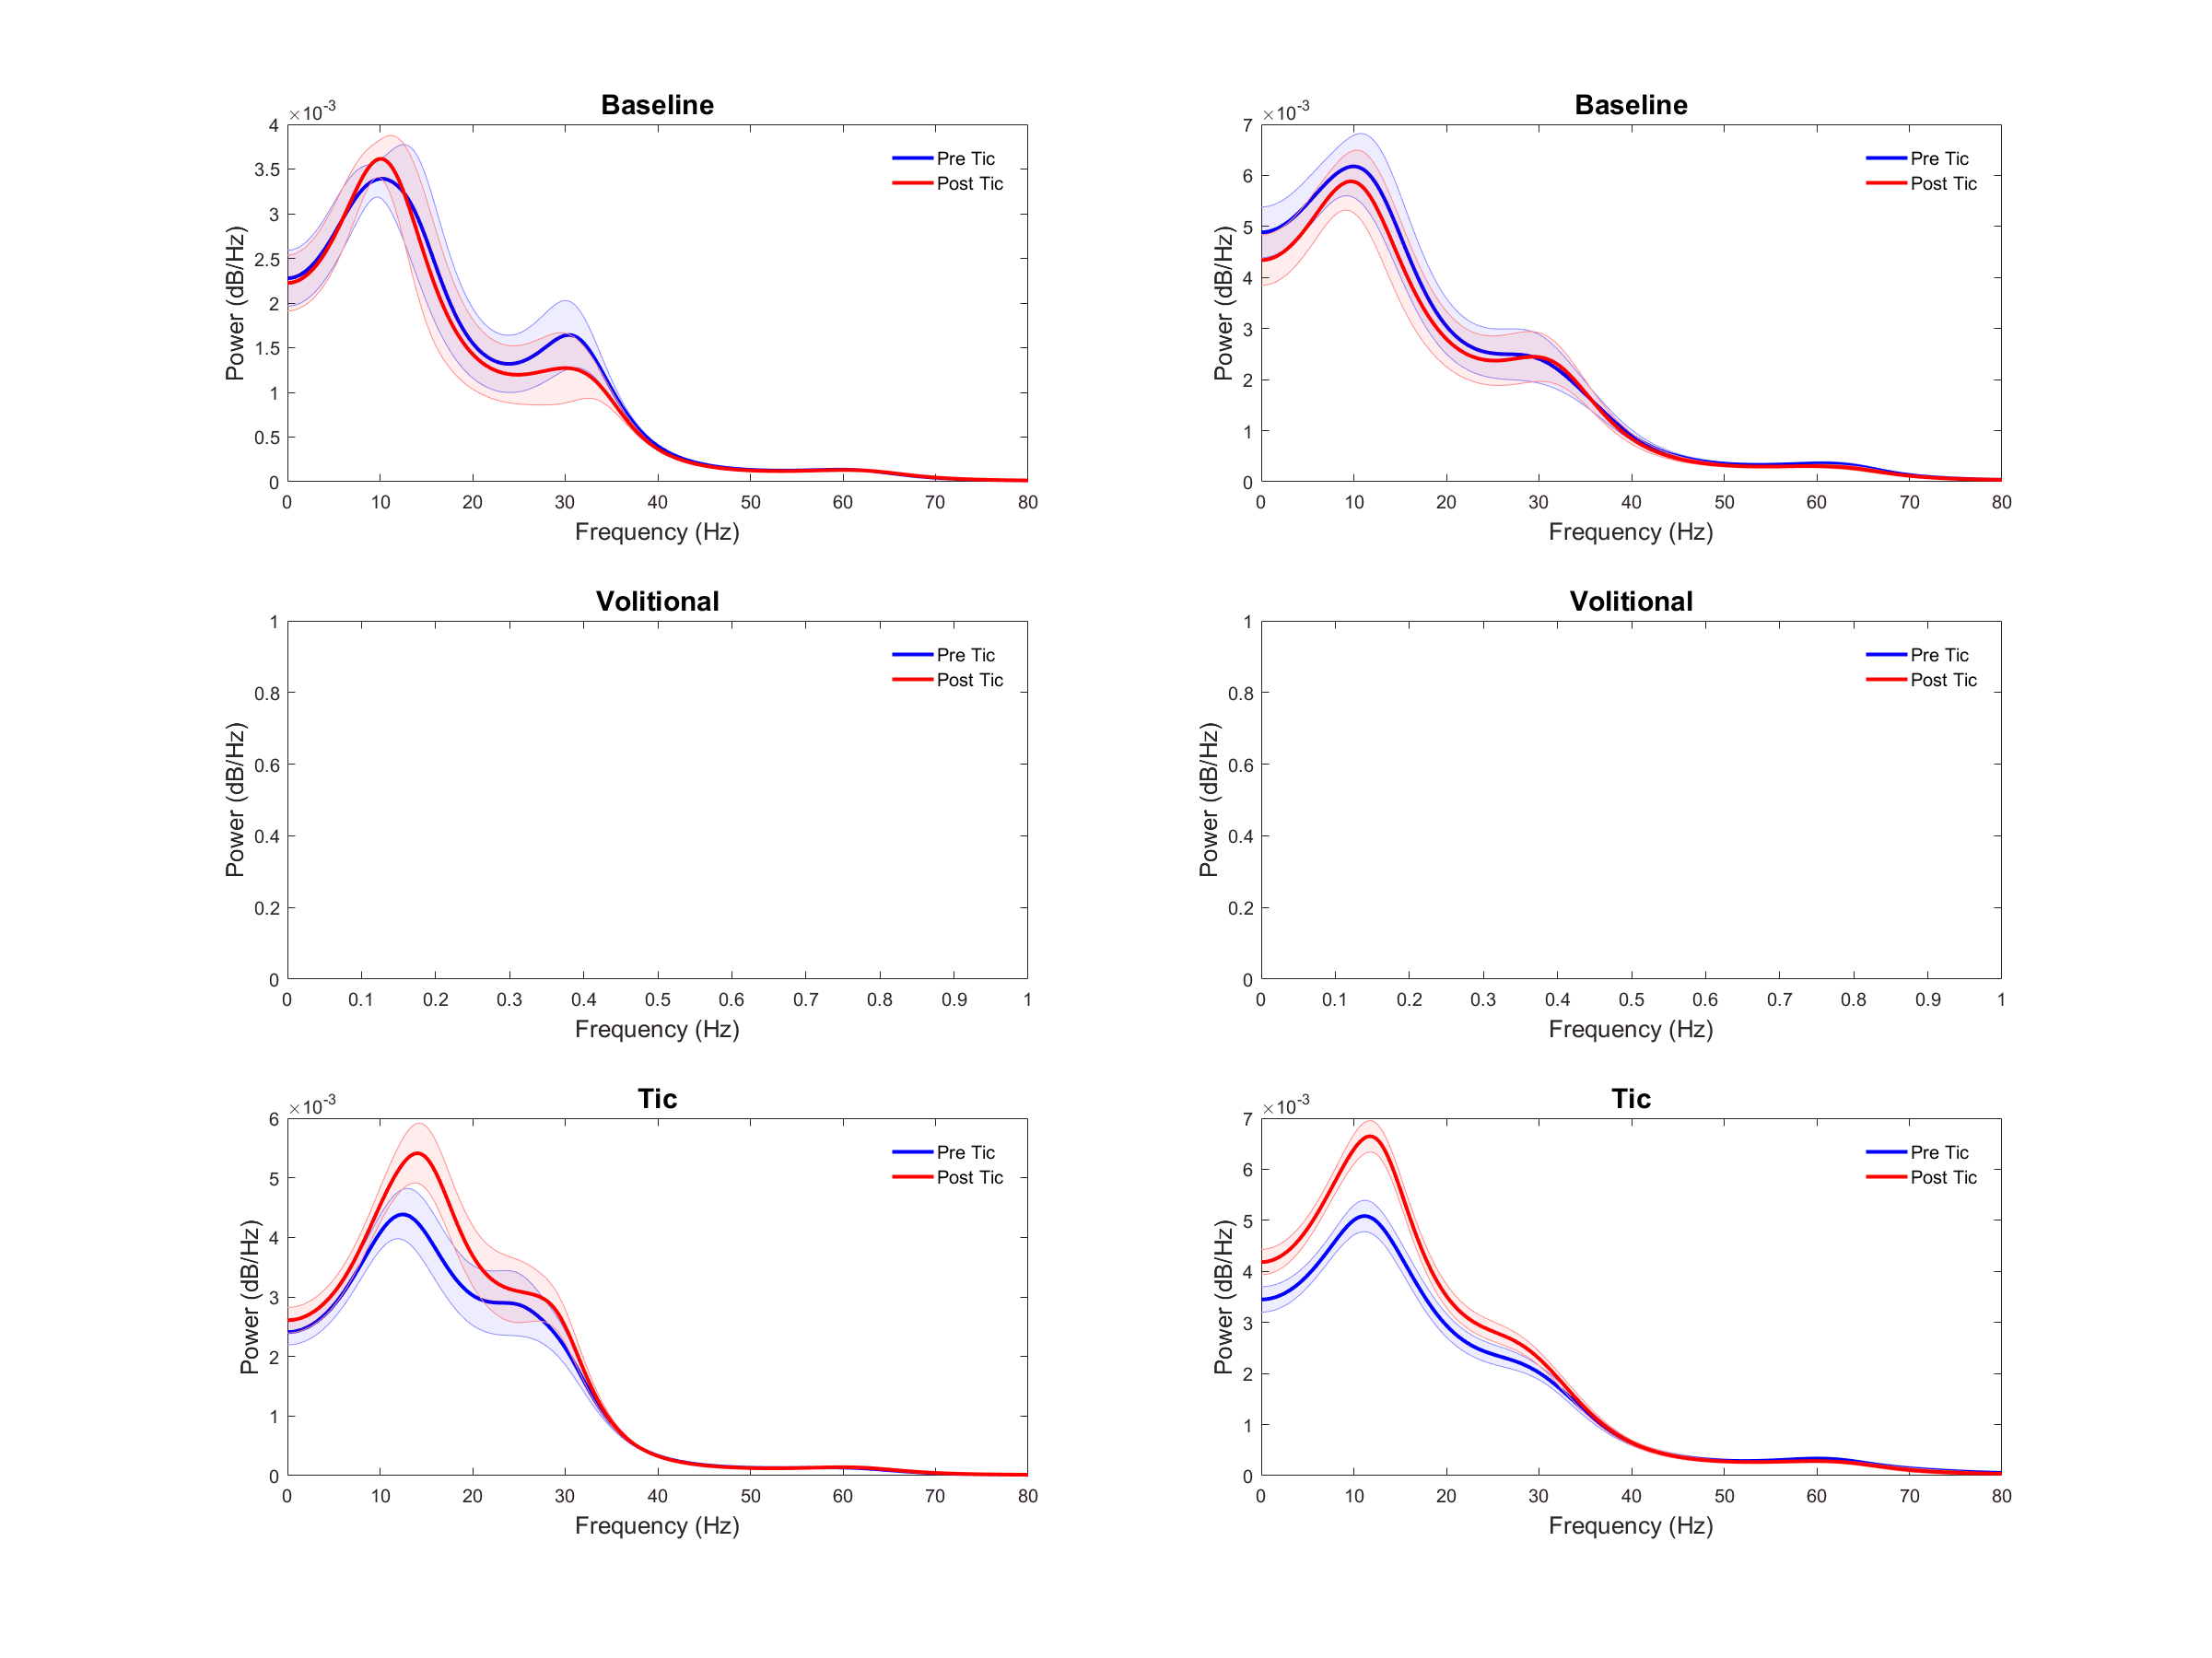

% Compute Power Spectral Density
Frequency = 0:0.1:80;
TimeRange = (ProcessedData(trial).Right_DBS.SamplingRate*TimeLimit(1):ProcessedData(trial).Right_DBS.SamplingRate*TimeLimit(2)) / ProcessedData(1).Right_DBS.SamplingRate;
PreTic = IndexRange < 0;
PostTic = IndexRange >= 0;
Pxx_Pre = cell(1,length(TicRecording));
Pxx_Post = cell(1,length(TicRecording));
for trial = 1:length(TicRecording)
    Fs = ProcessedData(trial).Left_DBS.SamplingRate;
    mem_params = configMem(12, Frequency, Fs, 'detrend', true, 'evalBin', 1);
    Pxx_Pre{trial} = zeros(length(Frequency),TicRecording(trial).Count,2);
    Pxx_Post{trial} = zeros(length(Frequency),TicRecording(trial).Count,2);
    for TicID = 1:TicRecording(trial).Count
        Pxx_Pre{trial}(:,TicID,1) = mem(TicRecording(trial).CorData(PreTic,TicID,1), mem_params);
        Pxx_Pre{trial}(:,TicID,2) = mem(TicRecording(trial).CorData(PreTic,TicID,2), mem_params);
        Pxx_Post{trial}(:,TicID,1) = mem(TicRecording(trial).CorData(PostTic,TicID,1), mem_params);
        Pxx_Post{trial}(:,TicID,2) = mem(TicRecording(trial).CorData(PostTic,TicID,2), mem_params);
    end
end

% Visualization (Left Side)
largeFigure(0, [1600 1200]); clf;
for subPlots = 1:6
    subplot(3,2,subPlots); cla; hold on; box on;
    DataSelection = TicRecording(subPlots).DataCompletion(:,1) == 3;
    H1 = shadedErrorBar(Frequency, mean(Pxx_Pre{subPlots}(:,DataSelection,1),2), std(Pxx_Pre{subPlots}(:,DataSelection,1),[],2) / sqrt(sum(DataSelection)), {'b', 'linewidth', 2}, 0.5);
    H2 = shadedErrorBar(Frequency, mean(Pxx_Post{subPlots}(:,DataSelection,1),2), std(Pxx_Pre{subPlots}(:,DataSelection,1),[],2) / sqrt(sum(DataSelection)), {'r', 'linewidth', 2}, 0.5);
    legendFont([H1.mainLine,H2.mainLine],{'Pre Tic','Post Tic'},{'fontsize',10});
    xlabel('Frequency (Hz)','fontsize',13);

    ylabel('Power (dB/Hz)','fontsize',13);
    title(TaskID{subPlots},'fontsize',15);
end
